# Aplicativo ecuaciones diferenciales de orden superior: sistema de un circuito eléctrico RLC

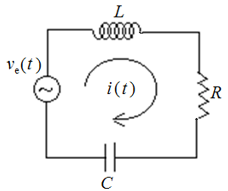


$$\left\{\begin{array}{l}
L\frac{d^2q}{dt}+R\frac{dq}{dt}+\frac{1}{C}q = v_e(t)\\[15pt]
q(0) = 0,\,\, \dot{q}(0) = 0
\end{array}\right.$$


**Parámetros:**

$L$: inductancia (en henrios, $H$)

$R$: resistencia eléctrica (ohmios, $\Omega$)

$C$: capacitancia (faradios, $F$)

**Interpretaciones:**

$\begin{array}{lcl}
v_e &=& v_L + v_R+v_c\\[15pt]
    &=& L\ddot{q} + R\dot{q}+\frac{1}{C}q
\end{array}$                   Ley de Kirchhoff de los voltajes

- voltaje de entradas: $v_e$

- Voltaje en el capacitor: $v_c=\frac{1}{C}q$

- Voltaje en el resistor: $v_R = R\dot{q}$

- Voltaje en el inductor: $v_L = \ddot{q}$

**Nota:** la relación entre carga y corriente es $i = \dot{q}$

**Modelo masa resorte vs modelo circuito eléctrico**


$$\begin{array}{cll}
L\ddot{q}+R\dot{q}+\frac{1}{C}q &=& v_e(t)\\[15pt]
 m\ddot{x}+f\dot{x}+kx &=& F_{ext}(t)
\end{array}$$


    con parámetros como:

        $x:$posición

        $m:$masa

        $f:$constante de fricción viscosa

        $k:$ constante elastica de resorte

        $F_{ext}:$ fuerza externa

**1. Hallar la solución simbólica para una entrada **$v_e = 1+0.5\sin(\omega t)$ con $\omega = 2\,rad/s$ como la frecuencia o velocidad angular. 

syms q(t)
%Definición  de parámetros
R = 1; L = 2; C = 2; omega = 2;
%Voltaje entrante
ve = 1 + 0.5*sin(omega*t);
%Definicion derivadas
Dq = diff(q,t,1);
D2q = diff(q,t,2);
%Ecuacion diferencial de orden superior
edo = L*D2q + R*Dq + q/C == ve;
%Condiciones iniciales
ci1 = q(0) == 0;
ci2 = Dq(0) == 0;
%Resolver la ecuación
carga = dsolve(edo,[ci1 ci2])

$$carga = \begin{array}{l} \sin\left(\sigma_{5}\right)\,\left(2\,\sin\left(\sigma_{5}\right)-\frac{15\,\sigma_{3}}{482}+\frac{15\,\sigma_{4}}{482}+\frac{2\,\sigma_{1}}{241}-\frac{2\,\sigma_{2}}{241}+\frac{2\,\sqrt{3}\,\cos\left(\sigma_{5}\right)}{3}-\frac{62\,\sqrt{3}\,\sigma_{3}}{723}-\frac{62\,\sqrt{3}\,\sigma_{4}}{723}+\frac{17\,\sqrt{3}\,\sigma_{1}}{1446}+\frac{17\,\sqrt{3}\,\sigma_{2}}{1446}\right)-\cos\left(\sigma_{5}\right)\,\left(\frac{2\,\sigma_{3}}{241}-2\,\cos\left(\sigma_{5}\right)+\frac{2\,\sigma_{4}}{241}+\frac{15\,\sigma_{1}}{482}+\frac{15\,\sigma_{2}}{482}+\frac{2\,\sqrt{3}\,\sin\left(\sigma_{5}\right)}{3}+\frac{17\,\sqrt{3}\,\sigma_{3}}{1446}-\frac{17\,\sqrt{3}\,\sigma_{4}}{1446}+\frac{62\,\sqrt{3}\,\sigma_{1}}{723}-\frac{62\,\sqrt{3}\,\sigma_{2}}{723}\right)-\frac{478\,{\mathrm{e}}^{-\frac{t}{4}}\,\cos\left(\sigma_{5}\right)}{241}-\frac{358\,\sqrt{3}\,{\mathrm{e}}^{-\frac{t}{4}}\,\sin\left(\sigma_{5}\right)}{723}\\ \mathrm{where}\\ \sigma_{1}=\sin\left(2\,t-\sigma_{5}\right)\\ \sigma_{2}=\sin\left(2\,t+\sigma_{5}\right)\\ \sigma_{3}=\cos\left(2\,t-\sigma_{5}\right)\\ \sigma_{4}=\cos\left(2\,t+\sigma_{5}\right)\\ \sigma_{5}=\frac{\sqrt{3}\,t}{4} \end{array}$$

%Simplificación
carga = simplify(carga)

$$carga = 2-\frac{15\,\sin\left(2\,t\right)}{241}-\frac{478\,{\mathrm{e}}^{-\frac{t}{4}}\,\cos\left(\frac{\sqrt{3}\,t}{4}\right)}{241}-\frac{358\,\sqrt{3}\,{\mathrm{e}}^{-\frac{t}{4}}\,\sin\left(\frac{\sqrt{3}\,t}{4}\right)}{723}-\frac{4\,\cos\left(2\,t\right)}{241}$$

%Factor común:
carga = collect(carga,'exp')

$$carga = \left(-\frac{478\,\cos\left(\frac{\sqrt{3}\,t}{4}\right)}{241}-\frac{358\,\sqrt{3}\,\sin\left(\frac{\sqrt{3}\,t}{4}\right)}{723}\right)\,{\mathrm{e}}^{-\frac{t}{4}}+2-\frac{15\,\sin\left(2\,t\right)}{241}-\frac{4\,\cos\left(2\,t\right)}{241}$$

%Cálculo de la amplitud y la fase:
amplitud = sqrt((15/241)^2 + (4/241)^2), fase = atan2(-4/241,-15/241)

amplitud = 0.0644

fase = -2.8810

%Cálculo de la corriente:
corriente = diff(carga,t,1);

**Gráfica de la entrada y la solución (observar el componente transitorio y el estacionario):**

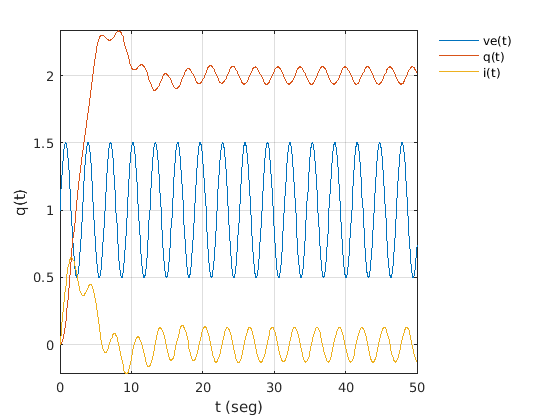

figure
fplot([ve,carga,corriente],[0 50])
legend({'ve(t)','q(t)','i(t)'},'Location','bestoutside','Box','off');
grid on
ylabel('q(t)')
xlabel('t (seg)')

Amplitud y fase aproximadas de la función de la carga en estado estacionario a partir del gráfico:

amplitud2 = 2.063-2

amplitud2 = 0.0630

fase2 = 2*(29-30.47) % fase = ω(t1 - t2), siendo t1 el tiempo de la señal de entrada (seno puro) y t2 de la señal desplazada

fase2 = -2.9400

**3. **Si la frecuencia angular ω de la entrada aumenta entre 2 y 10 con intervalos de $2 rad/s$, donde $V_e = \sin(\omega t)$, graficar el resultado y explicar lo que pasa con la amplitud y la fase de la salida.

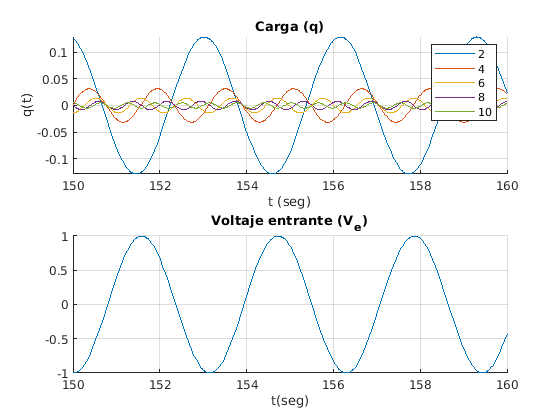

omegaV = 2:2:10;
figure
subplot(2,1,1)
title('Carga (q)')
for i = omegaV 
    edo = L*D2q + R*Dq + q/C == sin(i*t);
    Sol = dsolve(edo,[ci1 ci2]);
    hold on
    fplot(Sol,[150 160])
    grid on
end
legend(["2","4","6","8","10"])
ylabel('q(t)')
xlabel('t (seg)')

i = 1;
subplot(2,1,2)
title("Voltaje entrante (V_e)")
ve = sin(omegaV(i)*t);
hold on
fplot(ve,[150 160])
grid on
xlabel('t(seg)')

**4.** Graficar y analizar el resultado para los siguientes casos (explicar por qué físicamente al aumentar un parámetro ocurre lo que se observa por medio de una comparación con el sistema masa-resorte con fricción viscosa y las analogías mencionadas anteriormente):	

Inductancia $L$ aumenta y $v_e=1$

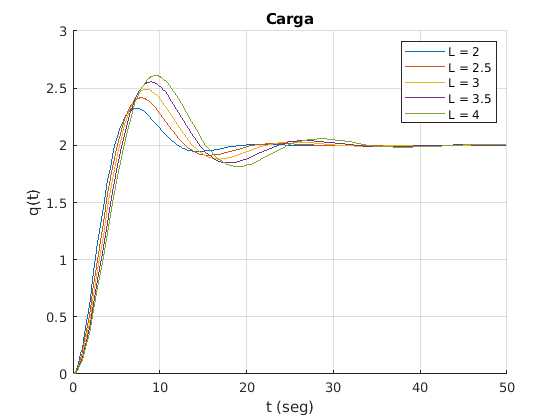

R = 1; L = 2:0.5:4; C = 2; 

figure
title('Carga')
for i = L 
    edo = i*D2q + R*Dq + q/C == 1;
    Sol = dsolve(edo,[ci1 ci2]);
    hold on
    fplot(Sol,[0 50])
    grid on
end
legend(["L = 2","L = 2.5","L = 3","L = 3.5","L = 4"])
ylabel('q(t)')
xlabel('t (seg)')

La resistencia $R$ aumenta y $v_e=1$

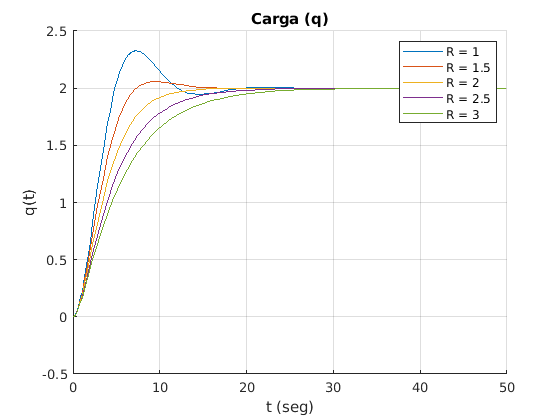

R = 1:0.5:3; L = 2; C = 2;

figure
title('Carga (q)')
for i = R
    edo = L*D2q + i*Dq + q/C == 1;
    Sol = dsolve(edo,[ci1 ci2]);
    hold on
    fplot(Sol,[0 50])
    grid on
end
legend(["R = 1","R = 1.5","R = 2","R = 2.5","R = 3"])
ylabel('q(t)')
xlabel('t (seg)')

La capacitancia $C$ aumenta y $v_e=1$

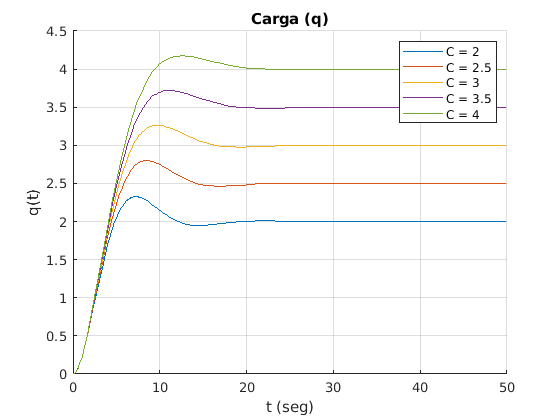

R = 1; L = 2; C = 2:0.5:4; 

figure
title('Carga (q)')
for i = C 
    edo = L*D2q + R*Dq + q/i == 1;
    Sol = dsolve(edo,[ci1 ci2]);
    hold on
    fplot(Sol,[0 50])
    grid on
end
legend(["C = 2","C = 2.5","C = 3","C = 3.5","C = 4"])
ylabel('q(t)')
xlabel('t (seg)')